### load dataset - simple contrast (dummy coding) stim Pain

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

con_list = dir(fullfile(mount_dir, '*/con_0010.nii'));
spm('Defaults','fMRI')
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0010.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25558272 bytes
Loading image number:    64
Elapsed time is 8.694013 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6187555  Bit rate: 22.56 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

### `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              15:55:49 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


drawnow; snapnow

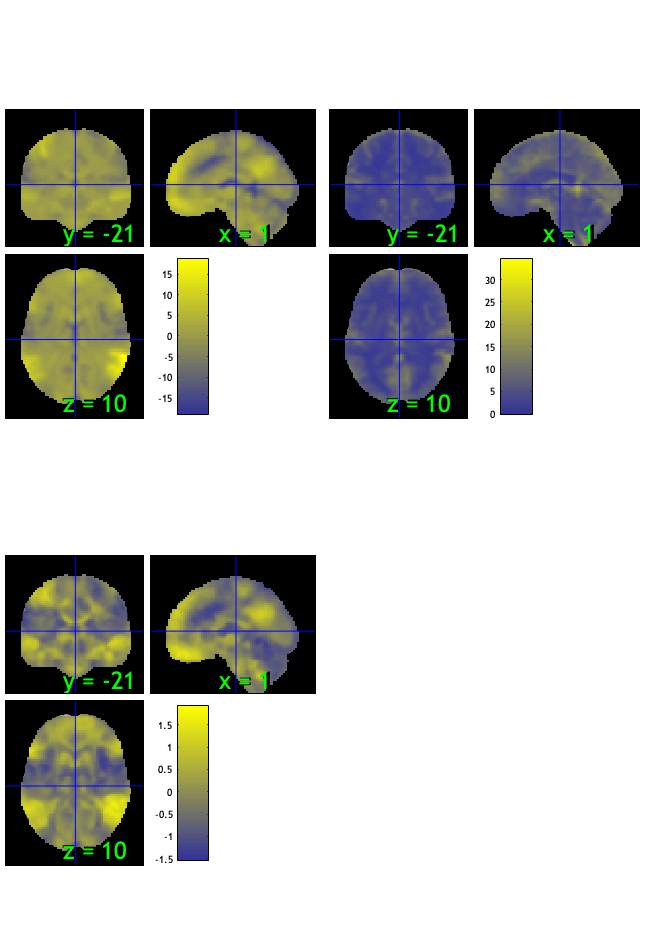

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.31%
Expected 3.20 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 2 24 33 35 38 
Uncorrected: 6 images		Cases 2 24 33 35 38 43 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.31%
Expected 3.20 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 11 
Uncorrected: 2 images		Cases 11 62 

Mahalanobis (cov and corr, q<0.05 corrected):
  6 images 
                               Outlier_count    Percentage
                         

SPM12: spm_check_registration (v7759)              15:56:19 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

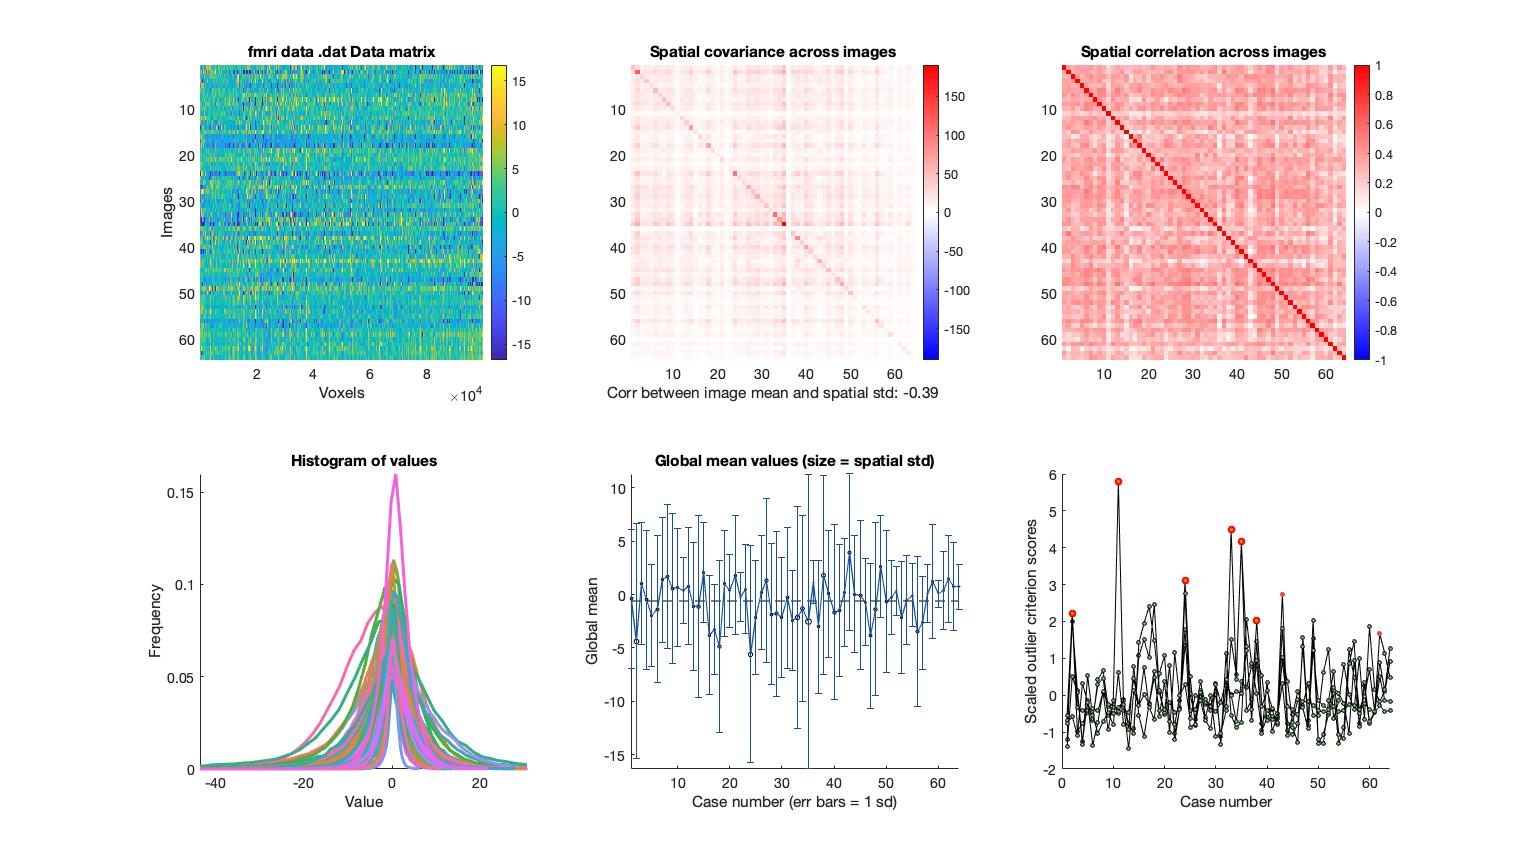

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


ans = 64×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


plot(con_data_obj)

drawnow; snapnow

### run robfit

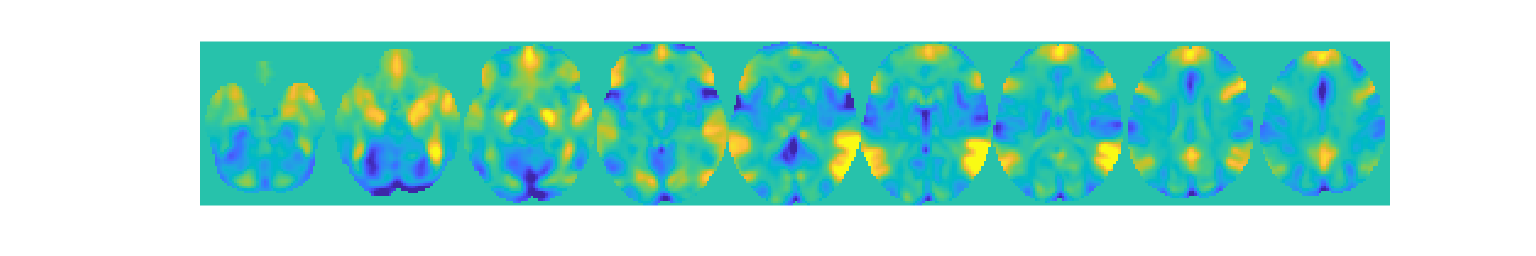

%set(gcf,'Visible','on')

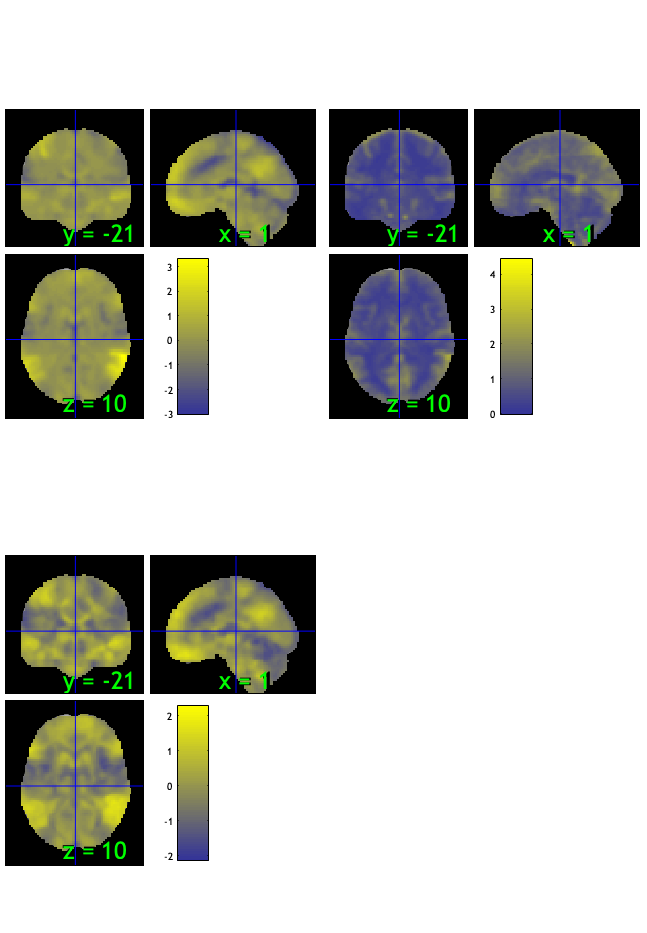

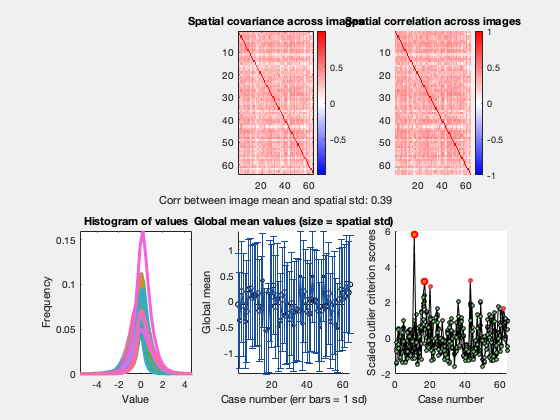

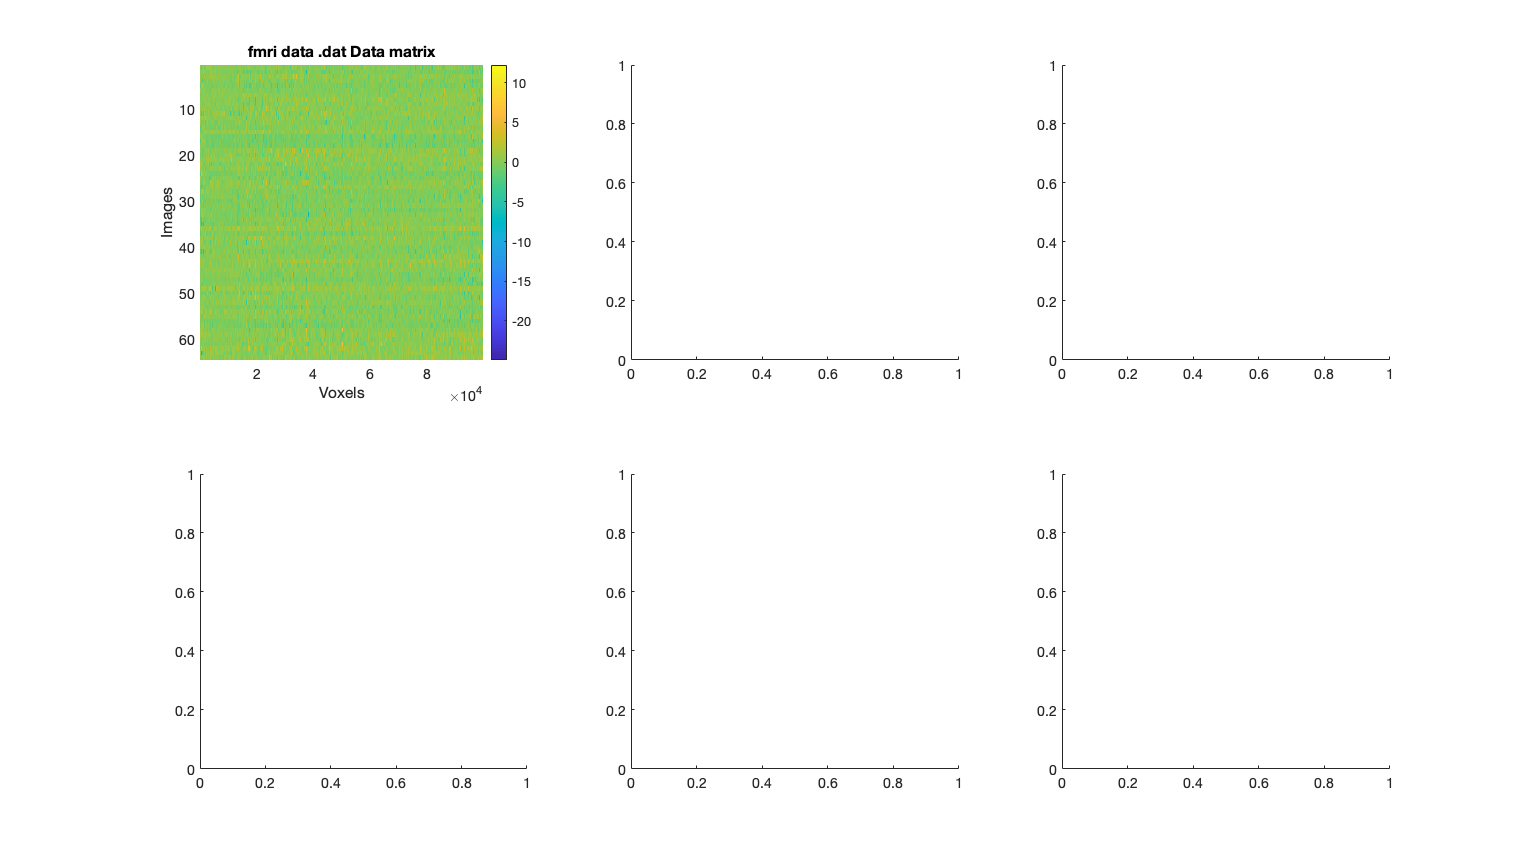

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 53.12%
Expected 3.20 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 20 43 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.31%
Expected 3.20 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 11 
Uncorrected: 2 images		Cases 11 62 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               __________

SPM12: spm_check_registration (v7759)              15:56:38 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


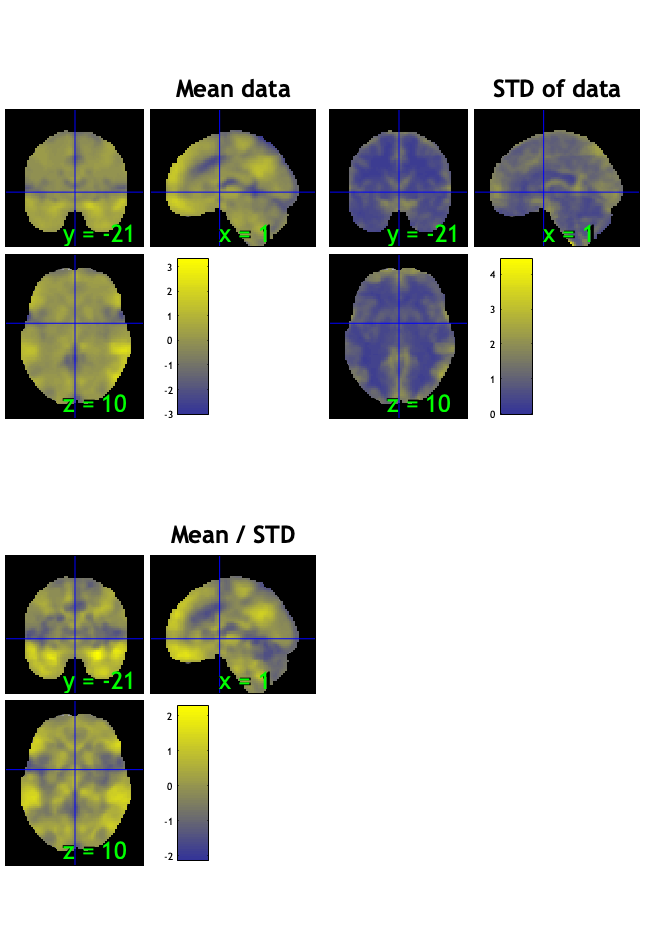

ans = 64×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


%figure ('Visible', 'on');

imgs2 = con_data_obj.rescale('l2norm_images');
plot(imgs2)

drawnow; snapnow


t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


t = threshold(t, .05, 'fdr', 'k', 10);  

Image   1 FDR q < 0.050 threshold is 0.032401

Image   1
  5 contig. clusters, sizes  12 to 63974
Positive effect: 27798 voxels, min p-value: 0.00000000
Negative effect: 36868 voxels, min p-value: 0.00000000


drawnow, snapnow;

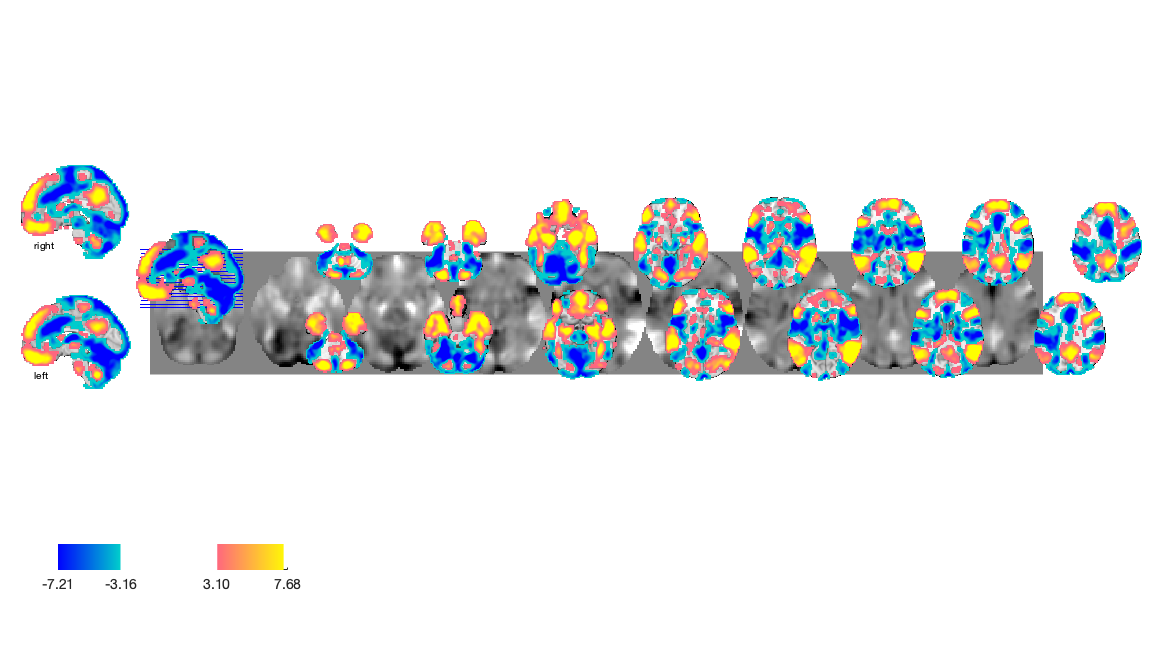

Setting up fmridisplay objects


sagittal montage: 1621 voxels displayed, 63045 not displayed on these slices


sagittal montage: 1642 voxels displayed, 63024 not displayed on these slices


sagittal montage: 1689 voxels displayed, 62977 not displayed on these slices


axial montage: 11821 voxels displayed, 52845 not displayed on these slices


axial montage: 12951 voxels displayed, 51715 not displayed on these slices


   % Show regions and print a table with labeled regions:
montage(t);  drawnow, snapnow;                  % Show results on a slice display

r = region(t);                                  % Turn t-map into a region object with one element per contig region

Grouping contiguous voxels:   5 regions


table(r);                                       % Print a table of results using new region names

____________________________________________________________________________________________________________________________________________
Positive Effects


sampleto = '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask.nii'

           Region             Volume             XYZ            maxZ       modal_label_descriptions      Perc_covered_by_label    Atlas_regions_covered    region_index
    ____________________    __________    _________________    ______    ____________________________    _____________________    _____________________    ____________

    {'Caudate_Ca_L'    }         12280     -5     12     11    5.2834    {'Basal_ganglia'           }             27                         3                  8      
    {'Bstem_Pons_L'    }          6424     -3    -22    -38      6.07    {'Brainstem'               }             37                         4                  6      
    {'Cblm_VIIb_L'     }           360    -32    -65   